## Problem 1

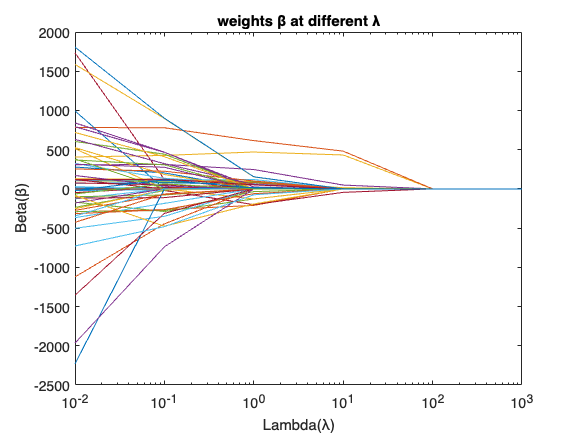

clear;
%load data
load('05HW1_diabetes.mat');
%set up variables
lambda = [0.01 0.1 1 10 100 1000];

%(a) get coefficients and fit lasso model
for i=1:size(lambda,2)
    [Beta(:,i),Fit(:,i)] = lasso(x_train,y_train,'Lambda',lambda(i),'CV',10);
end
%plot figure
figure;
semilogx(lambda,Beta);
title('weights β at different λ');
xlabel('Lambda(λ)');
ylabel('Beta(β)');

#### 隨著λ逐漸變大，β的絕對值(|β|)會越來越小，直到β＝0。

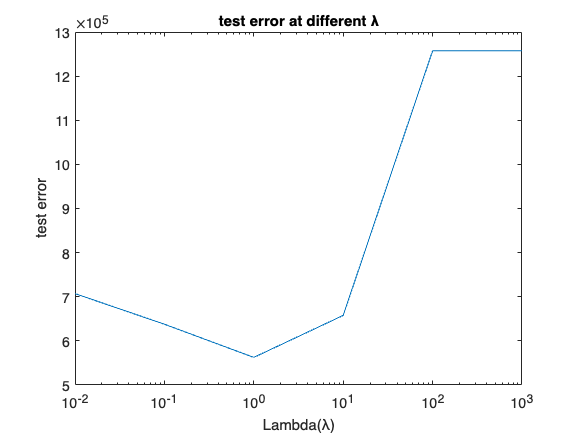

%(b) get predictions and calculate test error
for i=1:size(lambda,2)
    coef = Beta(:,i);
    % find intercept
    coef_0(i) = Fit(i).Intercept;
    y_hat(:,i) = x_test*coef + coef_0(i);
    error(i) = sum((y_hat(:,i)-y_test).^2);
end
%plot figure
figure;
semilogx(lambda,error);
title('test error at different λ');
xlabel('Lambda(λ)');
ylabel('test error');

#### λ = 0.01~1：test error下降

#### λ = 1：test error有最小值

#### λ = 1~100：test error上升

#### λ = 100~1000：上升程度趨緩

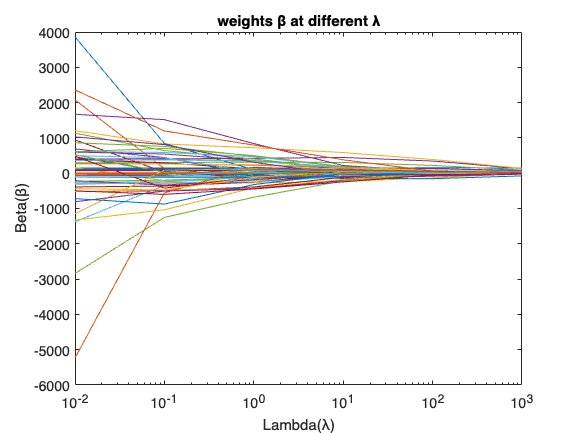

%(c) get the coefficient using ridge regression
BR = ridge(y_train,x_train,lambda,0); 
s=size(x_test,1);
rx_test=[ones(s,1) x_test];
yhat2 = rx_test*BR;
for i = 1:size(lambda,2)
    errR(i) = sum((yhat2(:,i)-y_test).^2);
end
figure;
semilogx(lambda,BR);
title('weights β at different λ');
xlabel('Lambda(λ)');
ylabel('Beta(β)');

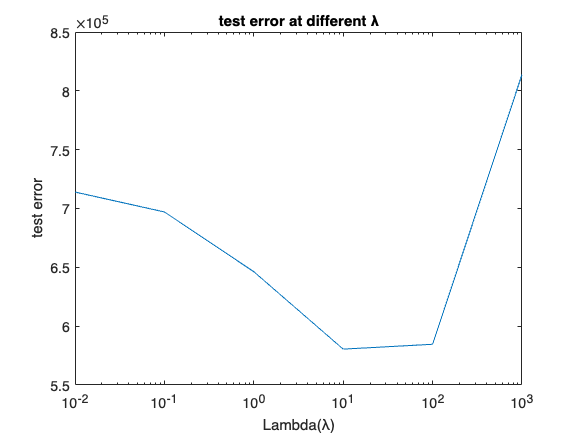

semilogx(lambda,errR);
title('test error at different λ');
xlabel('Lambda(λ)');
ylabel('test error');

由β v.s. λ圖可看出隨著λ越大，β將越來越小。

#### λ = 0.01~10：test error下降

#### λ = 10：test error有最小值

#### λ = 10~100：test error緩慢上升

#### λ = 100~1000：test error上升程度加快

## Problem 2

clear;
%load data
[xt1,xt2,xt3,xt4,xt5,xt6,xt7,xt8,xt9,xt10,xt11,y_train]=textread('05HW2_wine_training.txt','%f%f%f%f%f%f%f%f%f%f%f%f');
[xte1,xte2,xte3,xte4,xte5,xte6,xte7,xte8,xte9,xte10,xte11,y_test]=textread('05HW2_wine_test.txt','%f%f%f%f%f%f%f%f%f%f%f%f');
x_train=[xt1 xt2 xt3 xt4 xt5 xt6 xt7 xt8 xt9 xt10 xt11];
x_test=[xte1 xte2 xte3 xte4 xte5 xte6 xte7 xte8 xte9 xte10 xte11];
lambda = [0.0001 0.0005 0.0025 0.0125 0.0625 0.3125 1.5625 7.815 39.0625 195.3125];

%get the coefficient and fit into lasso model
for i=1:size(lambda,2)
    [B(:,i),FitInfo(:,i)]=lasso(x_train,y_train,'Lambda',lambda(i),'CV',10);
end
%get the prediction of the lasso model and calculate the error
for i=1:size(lambda,2)
    coef = B(:,i);
    coef0(i) = FitInfo(i).Intercept;
    yhat_train(:,i) = x_train*coef + coef0(i);
    train_err(i) = sum((yhat_train(:,i)-y_train).^2);
    yhat_test(:,i) = x_test*coef + coef0(i);
    test_err(i) = sum((yhat_test(:,i)-y_test).^2);
end

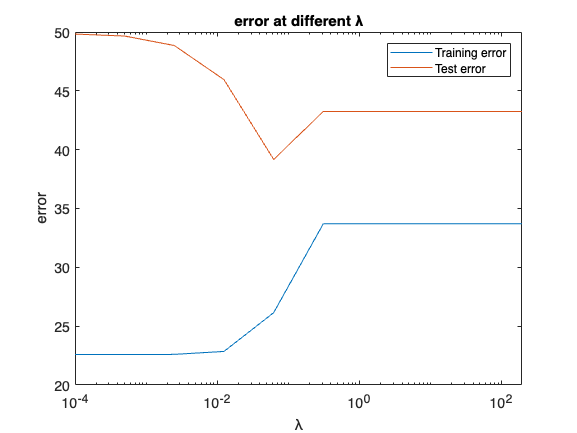

%(a) plot the Training error and Test error
figure;
semilogx(lambda,train_err,lambda,test_err);
title('error at different λ');
xlabel('λ'); ylabel('error');legend('Training error','Test error');

(b)

在λ＝0.0001, 0.0005, 0.0025, 0.0125, 0.0625 時，training error低，卻有偏高的test error，推測其應該有overfitting的狀況，model的variance很大。

在λ＝0.3125, 1.5625, 7.815, 39.0625, 195.3125 時，training error與test error皆相對較高，可推測其應該有underfitting的狀況。

(c)

選擇λ＝0.0625用來訓練final model，因為test error最低，且training error也還在可接受的範圍內。